winopen('EPLresults.xlsx')



EPL = readtable('EPLresults.xlsx');

x = rand(5,3)

x =     0.8089    0.6198    0.8914
    0.2368    0.9156    0.1312
    0.0472    0.0587    0.1950
    0.1696    0.5516    0.7630
    0.9595    0.7019    0.4479

y = array2table(x)

y =        x1          x2         x3   
    ________    ________    _______
      0.8089     0.61984    0.89142
     0.23677     0.91565    0.13122
    0.047198    0.058683    0.19497
     0.16961      0.5516    0.76297
     0.95954      0.7019    0.44792

z = table(4,5,4,2)

z =     Var1    Var2    Var3    Var4
    ____    ____    ____    ____
    4       5       4       2   


z.Properties.VariableNames = {'A','B','C','D'}

z =     A    B    C    D
    _    _    _    _
    4    5    4    2

byHomeWins = sortrows(EPL,'HomeWins','descend')

byHomeWins =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______
    'Arsenal'                 12          4             3            31        11         8          7             4            34        25    
    'Leicester City'          12          6             1            35        18        11          6             2            33        18    
    'Manchester City'         12 


EPL = sortrows(EPL,{'HomeWins','AwayWins'},'descend')

EPL =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______
    'Leicester City'          12          6             1            35        18        11          6             2            33        18    
    'Arsenal'                 12          4             3            31        11         8          7             4            34        25    
    'Manchester City'         12        

methods(EPL) % list of functions for an object


Methods for class table:

cat        ismember   setdiff    table      width      
height     join       setxor     union      
horzcat    ndims      size       unique     
innerjoin  numel      sortrows   unstack    
intersect  outerjoin  stack      varfun     
isempty    rowfun     summary    vertcat    




summary(EPL)

Variables:
    Team: 20×1 cell array of character vectors
    HomeWins: 20×1 double
        Description:  Original column heading: 'Home Wins'
        Values:
            min         2       
            median    7.5       
            max        12       
    HomeDraws: 20×1 double
        Description:  Original column heading: 'Home Draws'
        Values:
            min       2          
            median    5          
            max       9          
    HomeLosses: 20×1 double
        Description:  Original column heading: 'Home Losses'
        Values:
            min        1          
            median     5          
            max       12          
    HomeGF: 20×1 double
        Description:  Original column heading: 'Home GF'
        Values:
            min       14      
            median    29      
            max       47      
    HomeGA: 20×1 double
        Des

top10 = EPL(1:10,[1 2 7])

top10 =            Team            HomeWins    AwayWins
    ___________________    ________    ________
    'Leicester City'       12          11      
    'Arsenal'              12           8      
    'Manchester City'      12           7      
    'Manchester United'    12           7      
    'Southampton'          11           7      
    'Tottenham Hotspur'    10           9      
    'West Ham United'       9           7      
    'Liverpool'             8           8      
    'Stoke City'            8           6      
    'Swansea City'          8           4      


top10 = EPL(1:10,{'Team','HomeWins','AwayWins'})

top10 =            Team            HomeWins    AwayWins
    ___________________    ________    ________
    'Leicester City'       12          11      
    'Arsenal'              12           8      
    'Manchester City'      12           7      
    'Manchester United'    12           7      
    'Southampton'          11           7      
    'Tottenham Hotspur'    10           9      
    'West Ham United'       9           7      
    'Liverpool'             8           8      
    'Stoke City'            8           6      
    'Swansea City'          8           4      

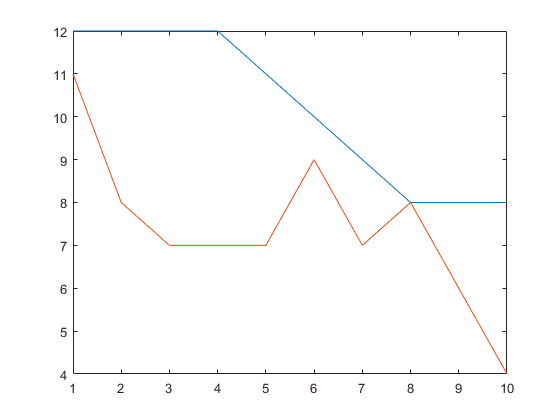

plot(top10{:,{'HomeWins','AwayWins'}})


% Curly for Content
T = top10(:,{'HomeWins','AwayWins'})

T =     HomeWins    AwayWins
    ________    ________
    12          11      
    12           8      
    12           7      
    12           7      
    11           7      
    10           9      
     9           7      
     8           8      
     8           6      
     8           4      

M = top10{:,{'HomeWins','AwayWins'}}

M =     12    11
    12     8
    12     7
    12     7
    11     7
    10     9
     9     7
     8     8
     8     6
     8     4


% Dot for Content
HomeWins = top10.HomeWins

HomeWins =     12
    12
    12
    12
    11
    10
     9
     8
     8
     8

vars = {'HomeWins','HomeDraws','HomeLosses'}

vars =     'HomeWins'    'HomeDraws'    'HomeLosses'

homeRecord = EPL{:,vars}

homeRecord =     12     6     1
    12     4     3
    12     2     5
    12     5     2
    11     3     5
    10     6     3
     9     7     3
     8     8     3
     8     4     7
     8     6     5

wins = EPL.HomeWins + EPL.AwayWins;
draws = EPL.HomeDraws + EPL.AwayDraws;
points = 3*wins + draws

points =     81
    71
    66
    66
    63
    70
    62
    60
    51
    47


EPL.Points = points

EPL =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______    ______
    'Leicester City'          12          6             1            35        18        11          6             2            33        18        81    
    'Arsenal'                 12          4             3            31        11         8          7             4     


standings = sortrows(EPL,'Points','descend')

standings =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______    ______
    'Leicester City'          12          6             1            35        18        11          6             2            33        18        81    
    'Arsenal'                 12          4             3            31        11         8          7             


writetable(standings,'EPLstandings.xlsx')

winopen('EPLstandings.xlsx')

EPL.Points = [] % deletes

EPL =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______
    'Leicester City'          12          6             1            35        18        11          6             2            33        18    
    'Arsenal'                 12          4             3            31        11         8          7             4            34        25    
    'Manchester City'         12        